## Pocket Sensei - Martial Arts Stance analysis

%% Collection rate of 10 Hz
Fs = 10;

## Visualizing our original data of 1 step each

Note: frontstance03.mat is anomolous

%% Select which stance to load
stance = 'frontstance0'

stance = 'frontstance0'

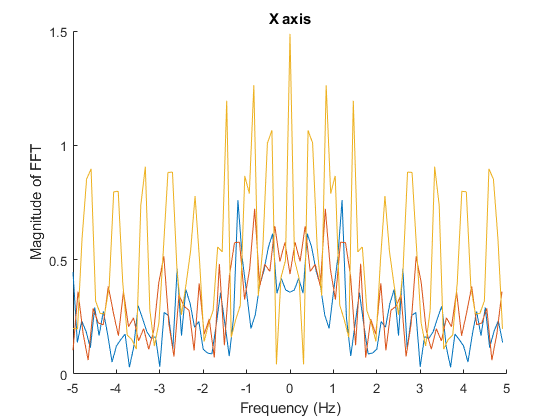

% stance = 'frontstance1'
% stance = 'sidestance'
% stance = 'backstance'

load([stance '1.mat'])
accel1 = Acceleration;
load([stance '2.mat'])
accel2 = Acceleration;
load([stance '3.mat'])
accel3 = Acceleration;

figure(1)
clf;
hold on;
simple_freq_plot(accel1, 1, Fs);
simple_freq_plot(accel2, 1, Fs);
simple_freq_plot(accel3, 1, Fs);
title("X axis")
hold off;

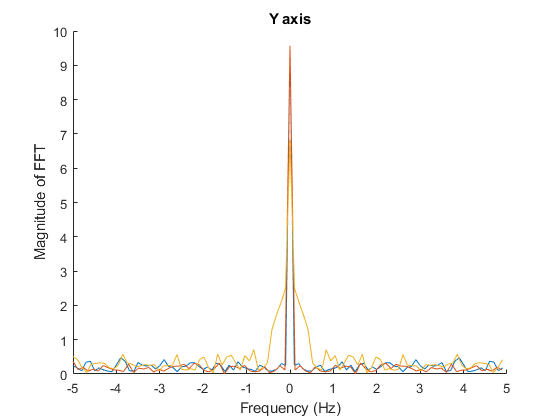


figure(2)
clf;
hold on;
simple_freq_plot(accel1, 2, Fs);
simple_freq_plot(accel2, 2, Fs);
simple_freq_plot(accel3, 2, Fs);
title("Y axis")
hold off;

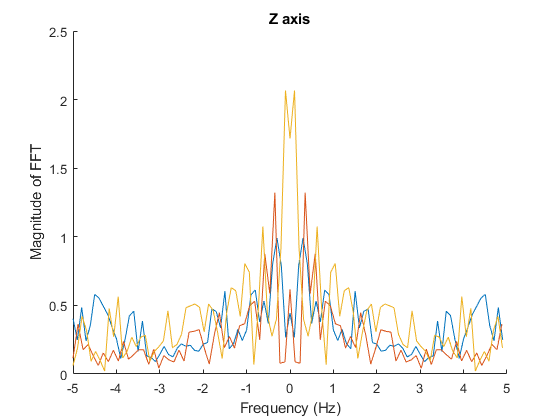


figure(3)
clf;
hold on;
simple_freq_plot(accel1, 3, Fs);
simple_freq_plot(accel2, 3, Fs);
simple_freq_plot(accel3, 3, Fs);
title("Z axis")
hold off;

## Load good and bad data for 10 steps

load fs_good.mat
accel_good = Acceleration;
load fs_bad.mat
accel_bad = Acceleration;

## y-axis analysis and graphs

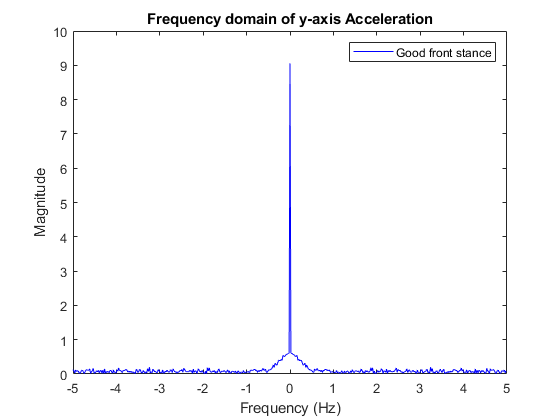

ylm = [0,10];
ffty_good = freq_plot(accel_good, 2, Fs, ylm, 'b');
legend("Good front stance")
ylabel("Magnitude")
xlabel("Frequency (Hz)")
title("Frequency domain of y-axis Acceleration")

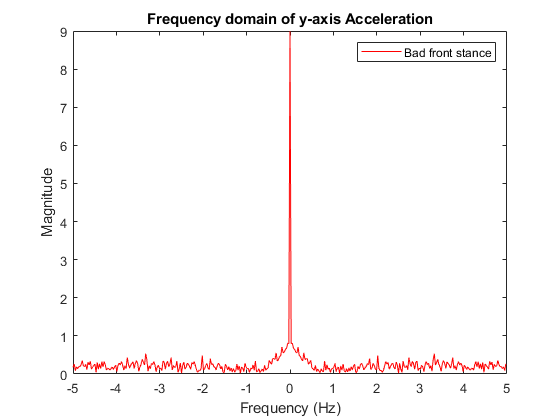


ffty_bad = freq_plot(accel_bad, 2, Fs, ylm, 'r');
legend("Bad front stance")
ylabel("Magnitude")
xlabel("Frequency (Hz)")
title("Frequency domain of y-axis Acceleration")


%higher better
good_ratio_y = y_algorithm(ffty_good)

good_ratio_y = 115.4123

bad_ratio_y = y_algorithm(ffty_bad)

bad_ratio_y = 45.6650

## x-axis analysis and graphs

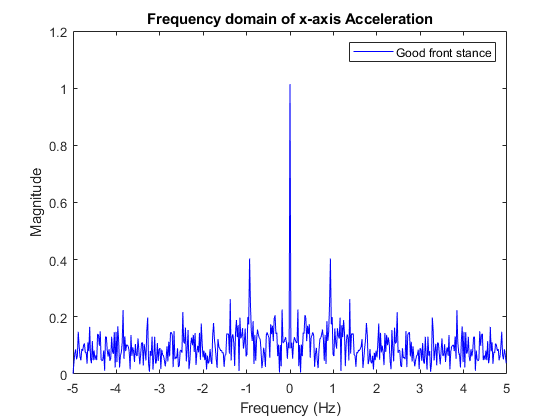

ylm = [0,1.1];
clf;
% hold on; 
fftx_good = freq_plot(accel_good, 1, Fs, ylm, 'b');
legend("Good front stance")
ylabel("Magnitude")
xlabel("Frequency (Hz)")
title("Frequency domain of x-axis Acceleration")

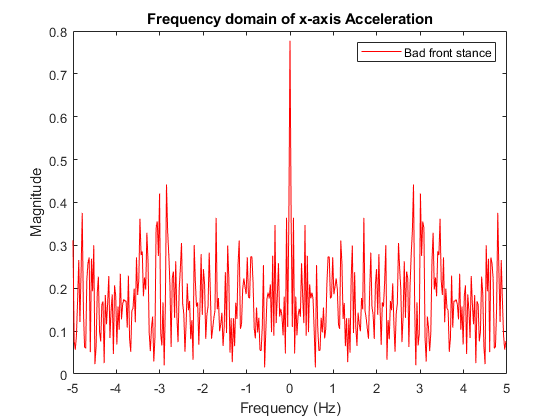


fftx_bad = freq_plot(accel_bad, 1, Fs, ylm, 'r');
legend("Bad front stance")
ylabel("Magnitude")
xlabel("Frequency (Hz)")
title("Frequency domain of x-axis Acceleration")


%higher better
good_ratio_x = x_algorithm(fftx_good)

good_ratio_x = 4.2160

bad_ratio_x = x_algorithm(fftx_bad)

bad_ratio_x = 2.6392

## z-axis analysis and graphs

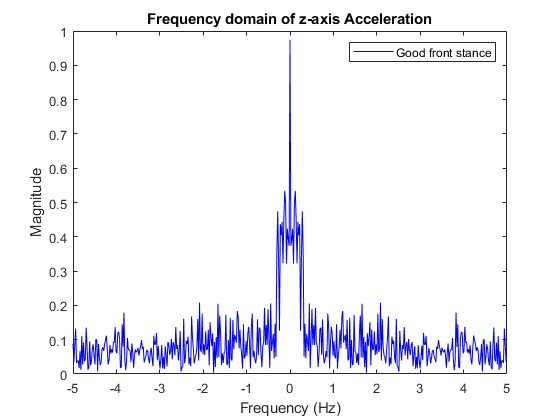

ylm = [0,1.1];
fftz_good = freq_plot(accel_good, 3, Fs, ylm, 'b');
legend("Good front stance")
ylabel("Magnitude")
xlabel("Frequency (Hz)")
title("Frequency domain of z-axis Acceleration")

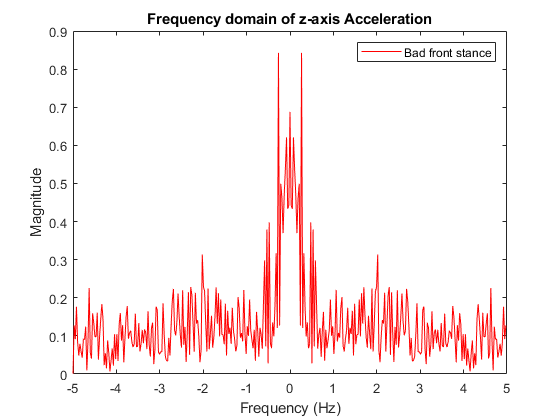


fftz_bad = freq_plot(accel_bad, 3, Fs, ylm, 'r');
legend("Bad front stance")
ylabel("Magnitude")
xlabel("Frequency (Hz)")
title("Frequency domain of z-axis Acceleration")


%higher better
good_ratio_z = z_algorithm(fftz_good)

good_ratio_z = 9.8815

bad_ratio_z = z_algorithm(fftz_bad)

bad_ratio_z = 5.0486

## Adding print feedback

zratio = bad_ratio_z;
xratio = bad_ratio_x;
yratio = bad_ratio_y;

% zratio = good_ratio_z;
% xratio = good_ratio_x;
% yratio = good_ratio_y;

if xratio > 4 && yratio > 100 && zratio > 8
    disp("Good job!")
elseif xratio < 2 || yratio < 30 || zratio < 4
    disp("Are you sure this is the right data?")
else
    if xratio > 2
        disp("Your side-to-side movement needs improvement. Try to keep your hips square with your shoulders, directly below your center of gravity.")
    end
    
    if yratio > 30
        disp("Your vertical movement needs improvement. Keep your hips level throughout the stance.")
    end
    
    if zratio > 4
        disp("Your forwards/backwards movement needs improvement. Try working on stopping cleanly between steps.")
    end
end

Your side-to-side movement needs improvement. Try to keep your hips square with your shoulders, directly below your center of gravity.


Your vertical movement needs improvement. Keep your hips level throughout the stance.


Your forwards/backwards movement needs improvement. Try working on stopping cleanly between steps.


## Algorithm functions

function ratio = x_algorithm(fftx)
    N =  length(fftx);
    fftx(round((N+1)/2))  =  0;
    fftx_trimmed = fftx(round(N/2):end);
    [M,I] = max(abs(fftx_trimmed));
    fftx_trimmed(I) = 0;
    ratio = M/mean(abs(fftx_trimmed));
end

function ratio = y_algorithm(ffty)
    N = size(ffty, 1);
    cutoff = round(N/2 + (N/2/10));
    ffty_trimmed = ffty(cutoff:end);
    [M,I] = max(abs(ffty));
    ratio = M/mean(abs(ffty_trimmed));
end
    
function ratio = z_algorithm(fftz)
    N =  length(fftz);
    zero_magnitude = abs(fftz(round((N+1)/2)));
    fftz_trimmed = abs(fftz(round(N/2):end));
    fftz_trimmed(1) = 0;
    ratio = zero_magnitude/mean(abs(fftz_trimmed));
end

## Plotting functions with timetable conversion

function output = freq_plot(accel, colNum, Fs, ylm, color)
    accel= (timetable2table(accel));
    accel= accel(:,2:end);
    accel = table2array(accel);
    make_freq_plot(accel(:,colNum), Fs, ylm, color)
    output = fftshift(fft(accel(:,colNum)));
end

function output = simple_freq_plot(accel, colNum, Fs)
    accel= (timetable2table(accel));
    accel= accel(:,2:end);
    accel = table2array(accel);
    make_freq_plot(accel(:,colNum), Fs, [], '-')
    output = fftshift(fft(accel(:,colNum)));
end

function output = time_plot(accel, colNum, Fs)
    accel= (timetable2table(accel));
    accel= accel(:,2:end);
    accel = table2array(accel);
    make_time_plot(accel(:,colNum), Fs)
    output = accel(:,colNum);
end

## Plotting functions

function make_freq_plot(x, Fs, ylm, color)
    % make a frequency domain plot with frequency labels
    %   x = input signal
    %   Fs = sampling frequency in Hz

    if(mod(length(x),2) ~=0)
        x = x(1:end-1);
    end

    plot(linspace(-Fs/2, Fs/2-Fs/length(x),length(x)), 1/length(x)*fftshift(abs(fft(x))), color)
    if size(ylm,1) == 2
        ylim(ylm)
    end

    ylabel('Magnitude of FFT');
    xlabel('Frequency (Hz)');
end

function make_time_plot(x, fs)
    % plot a time domain wave form for a given sampling rate
    %     x = waveform to be plotted
    %     fs = sampling rate

    plot([0:length(x)-1]/fs, x);
    l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', fs);
    xlabel(l);
end